Proper quantification of simulator dynamics, max motor per end = 1 vs multiple motors per end

**Max 1 motor per end**

rng('default');%initialize RNG for reproducibility

%choose params which support stable tug of war, ie
% high native processivity, low PG unbinding rate eps0<< koff0
% frequent PG binding, pi0>> kOn0
% otherwise based on experimental data rates

motorState.kOn0 = 0.5/60; %rate of single motor (synthase) binding to cargo (mreB) (From Stu data)
motorState.pi0 =10*motorState.kOn0; %single motor binding rate s^-1 %promotes tug of war
motorState.eps0=0.3/60;%single motor unbinding rate s^-1 %promotes tug of war, also at low concentration 
% derived from Stu data)
%processivity is synthesis limited
motorState.kOff0 = 10*motorState.eps0; %rate of single motor (synthase) unbinding from cargo (mreB)
motorState.Fdetach = 1;%detachment force pN nm
motorState.Fstall = 100; %stall force pN nM
motorState.vF=40;%forward velocity nm/s
motorState.vB=0.1;%backward velocity nm/s

motorState.Nplus=0;%initial total number of plus motors 
motorState.Nminus=0;%initial total number of bound plus motors 
motorState.nPlus=0;%number of bound plus motors 
motorState.nMinus=0;%number of bound minus motors

simPar.nStep= 100;


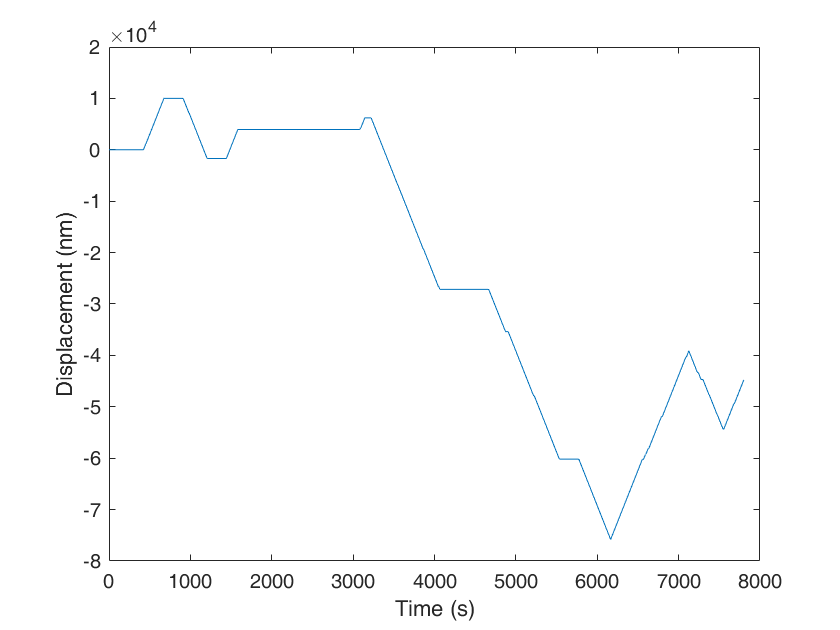

%Nmax = 1 each side (max number of motors), low concentration, which should give frequent pausing model
motorState.Nmax = 1;
motorState.motorConcentration =0.1;%arb units, essentiall scaling of low synthase concentration data here


[dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
t=dynamics.t;
x=dynamics.x;
figure;
plot(t,x);
ylabel('Displacement (nm)');
xlabel('Time (s)');

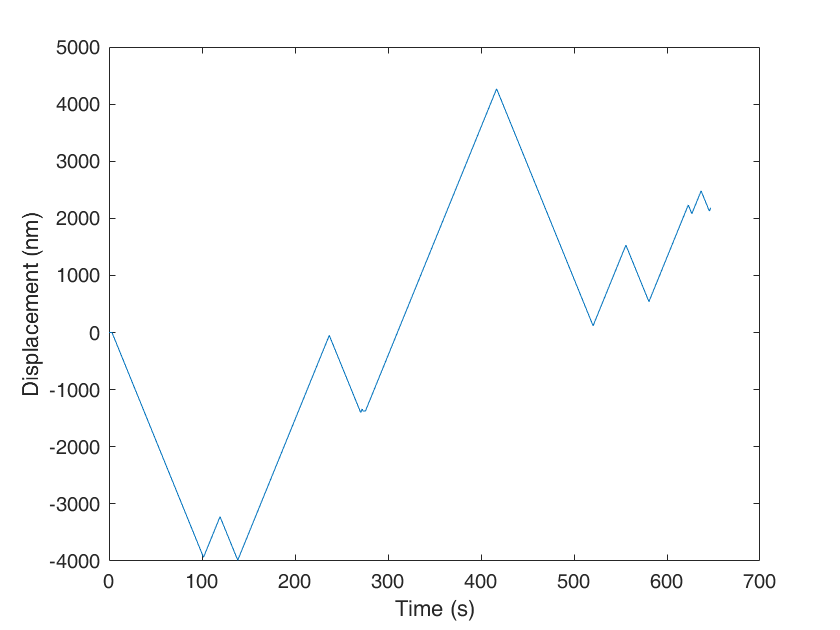

%Nmax = 1 each side, high concentration,  which should give frequent reversals
motorState.Nmax = 1;
motorState.motorConcentration =10;%arb units, essentiall scaling of low synthase concentration data here


[dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
t=dynamics.t;
x=dynamics.x;
figure;
plot(t,x);
ylabel('Displacement (nm)');
xlabel('Time (s)');

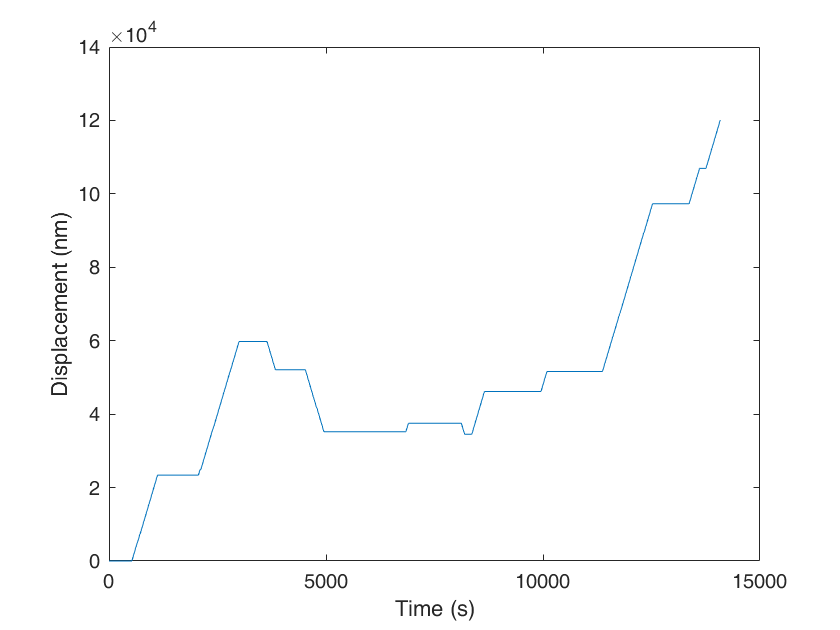

%Nmax = inf each side, low concentration which should give frequent pausing
motorState.Nmax = inf;
motorState.motorConcentration =0.1;%arb units, essentiall scaling of low synthase concentration data here
[dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
t=dynamics.t;
x=dynamics.x;
figure;
plot(t,x);
ylabel('Displacement (nm)');
xlabel('Time (s)');

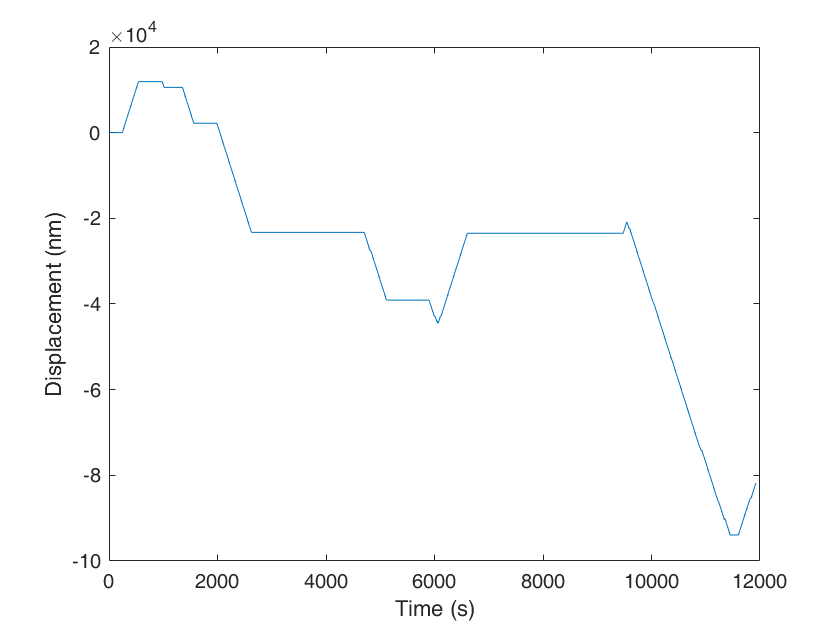

%Nmax = inf each side, high concentration which lipowski predicts should give
%infrequent pausing, relatively infrequent reversals but high processivity
motorState.Nmax = inf;
motorState.motorConcentration =0.1;%arb units, essentiall scaling of low synthase concentration data here
[dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
t=dynamics.t;
x=dynamics.x;
figure;
plot(t,x);
ylabel('Displacement (nm)');
xlabel('Time (s)');

**initial rates etc analysis**

motorConcRange = 10.^(0:4).*0.01

motorConcRange =     0.0100    0.1000    1.0000   10.0000  100.0000



analysisPar.frameInterval = 6;
analysisPar.zeroSpeedThresh = 5;
analysisPar.switchTooCloseThresh = 4;
nSimRepeat=100

nSimRepeat = 100

**Max motor = 1**

motorState.Nmax = 1;

for ii = 1:numel(motorConcRange)
    motorState.motorConcentration =motorConcRange(ii);
    [processivityNmax1{ii}, speedNmax1{ii}, lifetimeNmax1{ii}, rateNmax1{ii}, fractionMotileNmax1{ii}, simResultNmax1{ii}] =...
     quantifySimDynamics(motorState, simPar,analysisPar,nSimRepeat);
end